# Extending Network training to regression tasks

clear all; close all; clc;
addpath('..\')

## R->R function

We want the network to learn a real valued function

f = @(x) sin(10*x);

We start by sampling some training points in the interval [a_, b_]

n_train = 50;
a_ = 0; b_ = 1;
x = sort(a_ + (b_ - a_).*rand(n_train, 1))';
y = f(x);

Specify some hyperparameters of the network.

**Note: we switched from **`sigmoid`** to **`tanh`** activation function**

niter = 5e3;
shape = [1, 30, 30, 30, 30, 1];
sigma = @(t) tanh(t);
sigmaprime = @(t) 1 - tanh(t).^2;
eta = 0.005;

### Training

Train the network (or load pre-trained weights)

[costHistory, W, b] = GradientDescent(...
    x, y, niter, sigma, sigmaprime, eta, shape);

10.0%
20.0%
30.0%
40.0%
50.0%
60.0%
70.0%
80.0%
90.0%
100.0%


save sin10xNNparams.mat W b costHistory
% load sin10xNNparams.mat

Plot the evolution of the cost function

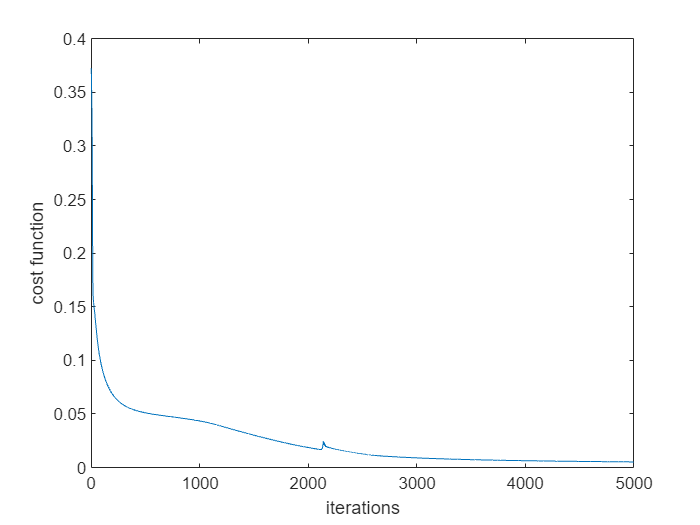

figure
plot(linspace(0,niter,niter)', costHistory, '-')
xlabel('iterations')
ylabel('cost function')

fprintf('Cost Function: %f\n', costHistory(end));

Cost Function: 0.005211


### Test

We sample some other data to perform the testing.

n_test = 100;
x_test = linspace(0, 1, n_test);
y_test = f(x_test);

Let the test data flow throught the network to get the predictions

y_pred = PredictRegression(W, b, sigma, x_test);

### Plot results

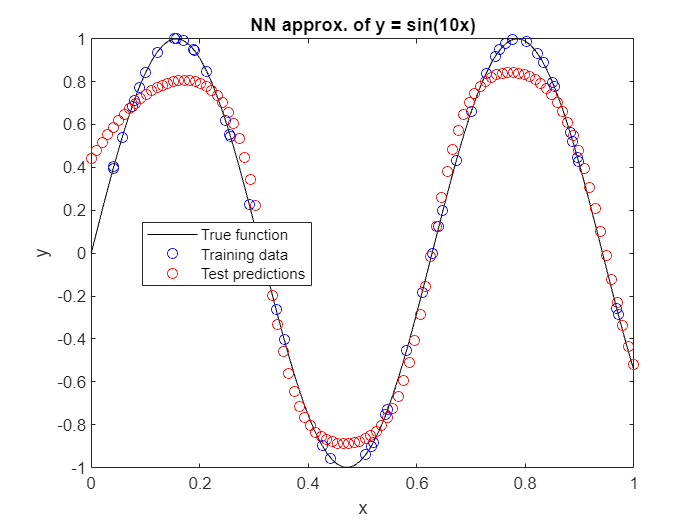

figure;
plot(x_test, y_test, 'k-');
hold on;
scatter(x, y, 'bo'); % Training data (blue dots)
scatter(x_test, y_pred, 'ro'); % Test predictions (red dots)
legend('True function', 'Training data', 'Test predictions', Location='best');
xlabel('x');
ylabel('y');
title('NN approx. of y = sin(10x)');

### Compute errors

errorL2 = norm(y_pred-y_test);
errorLp = norm(y_pred-y_test, 10);
errorInf = norm(y_pred-y_test, "inf");
disp(['error L^2: ', num2str(errorL2), ' error L^\infty: ', num2str(errorInf)]);

error L^2: 1.1878 error L^\infty: 0.44311


## R^2->R function$u$

clear all; clc;

Now, the same task can be poerformed in a more involved case, considering a function from $\mathbb{R}^2\mapsto\mathbb{R}$ (that can still be visualized).

f = @(x1, x2) sin(10 * x1) + cos(10 * x2);

As done before, we sample some training data.

n_train = 1000;
x1 = rand(1, n_train);
x2 = rand(1, n_train);
x = [x1; x2];
y = f(x1, x2);

and specify some hyperparameters of the network

niter = 2e3;
shape = [2, 32, 64, 64, 32, 1];
sigma = @(t) tanh(t);
sigmaprime = @(t) 1 - tanh(t).^2;
eta = 0.01;

### Training

% [costHistory, W, b] = GradientDescent(...
%         x, y, niter, sigma, sigmaprime, eta, shape);
% save R2function W b costHistory
load R2function.mat

Plot of the cost function:

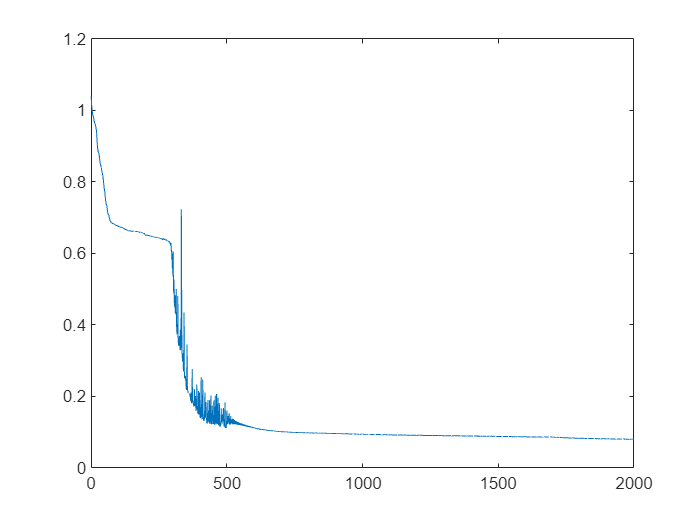

figure
plot(linspace(0,niter,niter)', costHistory, '-')

fprintf('Cost Function: %f\n', costHistory(end));

Cost Function: 0.079276


### Test

As done before, we sample some test data

n_test = 30;
x1_test = linspace(0, 1, n_test);
x2_test = linspace(0, 1, n_test);
[X1_test, X2_test] = meshgrid(x1_test, x2_test);
X_test = [X1_test(:), X2_test(:)]';
Y_test = f(X1_test,X2_test);

And, using the network, we compute the predictions:

y_pred = PredictRegression(W, b, sigma, X_test);

### Plot results

Since it's more difficult to visualize overlaffing 3D data, we plot the training points and the approximated functions in two different subplots.

Plot training data and exact function:

%%
figure;
subplot(1, 2, 1)
scatter3(x1, x2, y, 'bo'); % training data
hold on;
surf(X1_test, X2_test, Y_test); % exact function
title("Function sin(10x_1) + cos(10x_2)")
xlabel('x1'); ylabel('x2'); zlabel('y');
% legend('Training data')

Plot the approximated function in the test points:

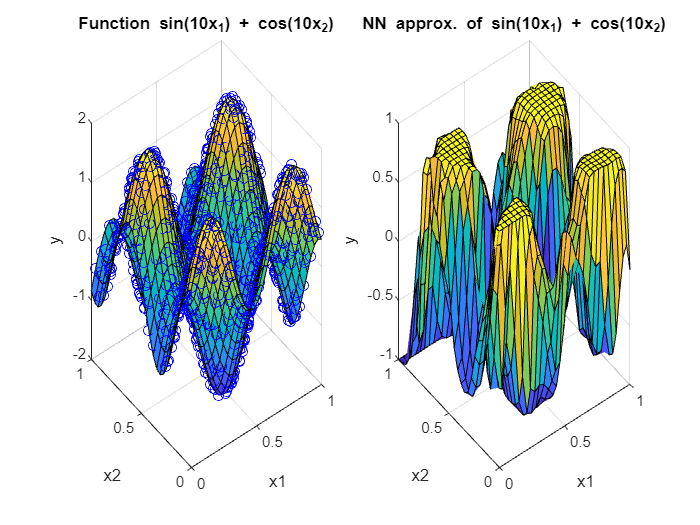

y_pred_matrix = reshape(y_pred, [30, 30]);
subplot(1, 2, 2)
surf(X1_test, X2_test, y_pred_matrix); % test predictions
title("NN approx. of sin(10x_1) + cos(10x_2)")
% legend('Test predictions');
xlabel('x1'); ylabel('x2'); zlabel('y');

### Compute errors

errorL2 = norm(Y_test(:) - y_pred)

errorL2 = 891.7554

errorInf = norm(Y_test(:) - y_pred, "inf")

errorInf = 1.8355e+03

disp(['error L^2: ', num2str(errorL2), ' error L^\infty: ', num2str(errorInf)]);

error L^2: 891.7554 error L^\infty: 1835.5088
